# Inelastic Scattering Probabilities

Thierry Lasserre

LastUpdated: 21/3/2018

## Read MC File

in inputs/WGTSMACE/

isp=load('IS-LookupTable-Trials-1000-2.5e+17-molPercm2-NIS-11.mat');
isp

isp = struct with fields:
         obj: [1×1 TBD]
       Pis_m: [11×1000 double]
       PisCM: [11×11 double]
    Pis_mean: [11×1 double]


## Plot no-scattering probability

ans = 'Plot #1: mean=61.94, std=6.49, 2 points counted in the rightmost bin are greater than 86.53 , '

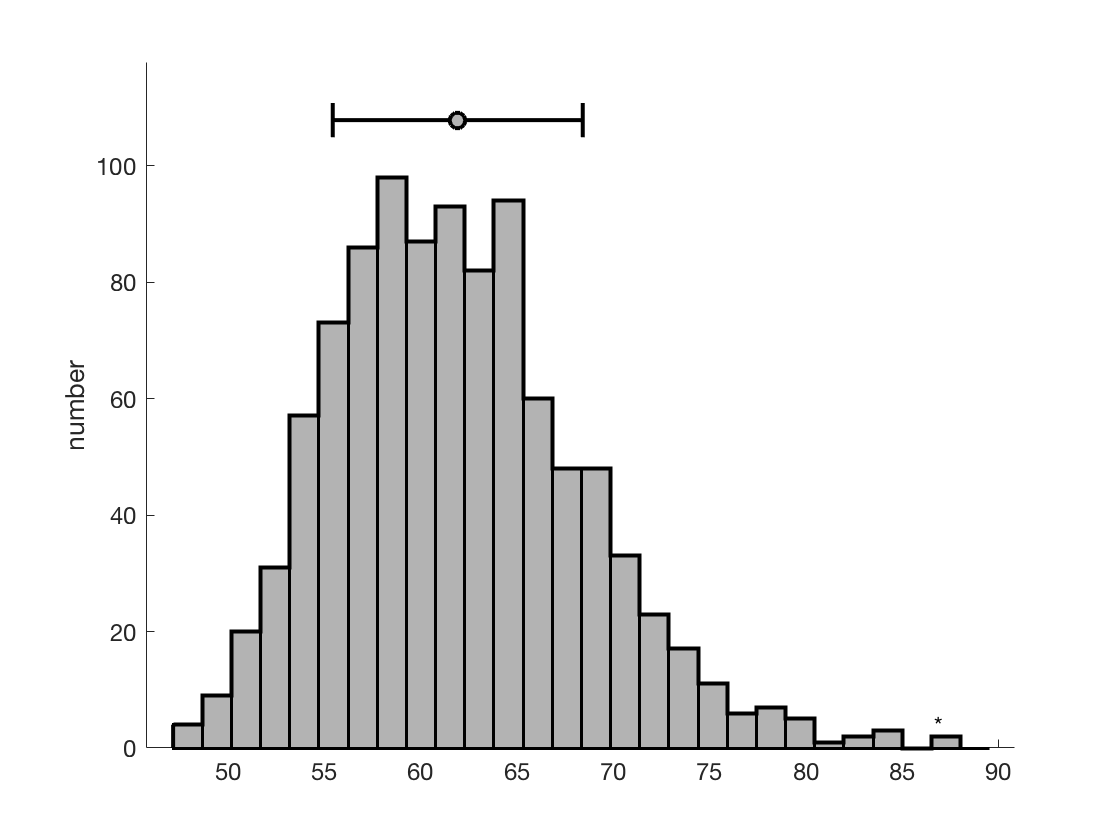

nhist(isp.Pis_m(1,:))

## Plot 1-scattering probability

ans = 'Plot #1: mean=27.20, std=2.85, 1 points counted in the rightmost bin are greater than 38.54 , '

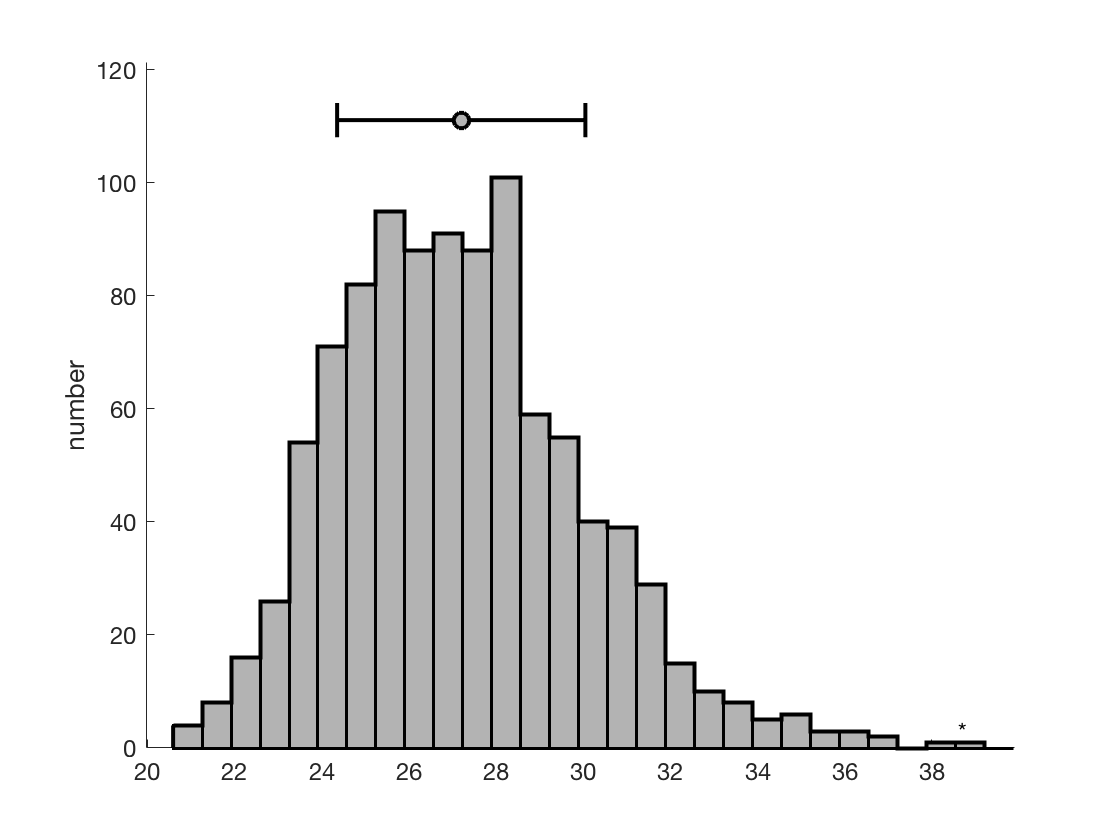

nhist(isp.Pis_m(2,:))

## Plot 2-scattering probability

ans = 'Plot #1: mean=8.86, std=0.93, 1 points counted in the rightmost bin are greater than 12.50 , '

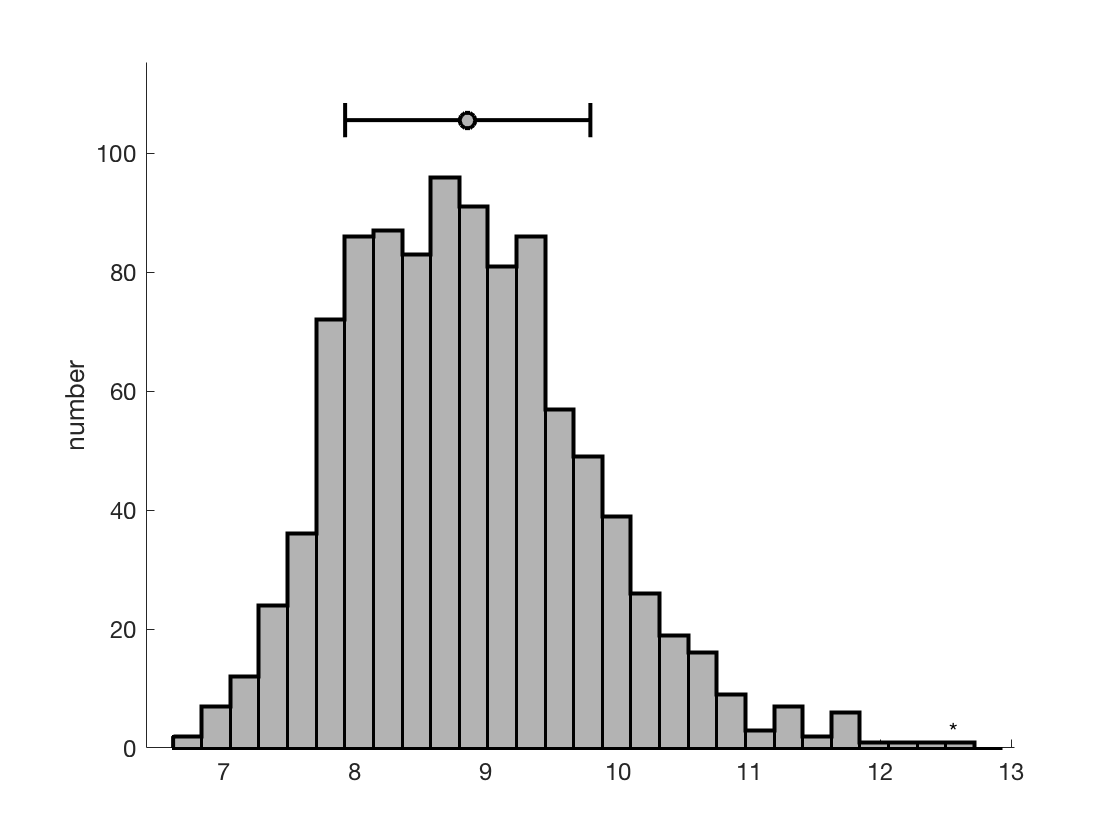

nhist(isp.Pis_m(3,:))

## Plot 3-scattering probability

ans = 'Plot #1: mean=8.86, std=0.93, 1 points counted in the rightmost bin are greater than 12.50 , '

nhist(isp.Pis_m(3,:))

## Plot Covariance Matrix

- 1=no scattering

- 2...11: 1 to 10th scattering

CovMat = PisCM;

Undefined function or variable 'PisCM'.

imagesc(CovMat);
colorbar;
title('IS Covariance Matrix')


## Plot Correlation Matrix

- 1=no scattering

- 2...11: 1 to 10th scattering

corplot(CovMat);
title('IS Correlation Matrix')
colorbar;